# Ultra Mega Sort 2000

## File selection

Next, we can search for the file to sort by running the following line:

[fileName, filePath] = uigetfile({'*.mat';'*.smr';'*.smrx'},'Choose file(s) to sort:','multiselect','off');
channelOrder = 'poly';
switch channelOrder
    case 'poly'
        chOrd = [8, 9, 7, 10, 4, 13, 5, 12, 2, 15, 1, 16, 6, 11, 3, 14];
    case 'linear'
        chOrd = [];
    case 'other'
        chOrd = 1;
end
dataLoader = UMSDataLoader(fullfile(filePath,fileName),chOrd);

Deleting...
Constructed!


You can now visualize the data if you like:

dataLoader.plot

ans =   Figure (1: UltraMegaSort2000 data) with properties:

      Number: 1
        Name: 'UltraMegaSort2000 data'
       Color: [1 1 1]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


## Parameters initialization

First, we define the spike structure for the detection parameters. The sampling frequency will be red from the input file and it is not necessary to give it. By default it is set in 20 kHz. All the values are default. You can easily change the value of a parameter by sliding the bars.

spikes = ss_default_params(dataLoader.SamplingFrequency,... Sampling frequency (from file)
    'thresh',4.1,... Detection threshold
    'window_size',1.5,... Spike size (ms)
    'shadow',0.75,... Inforced refractory period (ms)
    'cross_time',0.6,... Alignment point for peak of waveform (ms)
    'refractory_period',2.5,... Not really a refractory period (ms)
    'max_jitter',0.6,... Width of the window used for peak detection (ms)
    'agg_cutoff',0.05,... Higher --> less aggregation
    'kmeans_clustersize',500); % Number of maximum miniclusters

## Spike sorting

The spike sorting step loops throught the UMS interface to cluster the found units. You can select how many channels you want per pack and if you want overlap.

Deleting...
Constructed!
Detected on average 346.6567 events per second of data 


Figure closed. Search for the spikes
Figure closed. Search for the spikes
Detected on average 435.69 events per second of data 


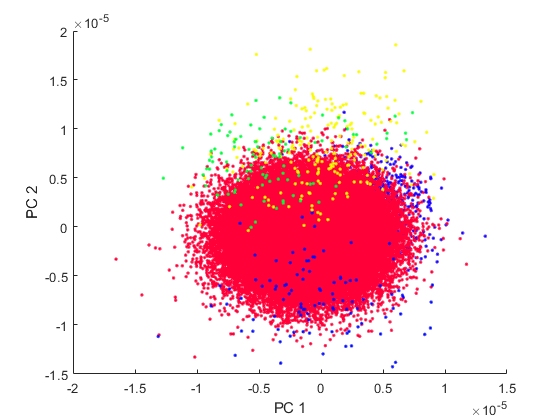

Figure closed. Search for the spikes
Figure closed. Search for the spikes
Detected on average 35.14 events per second of data 


Figure closed. Search for the spikes
Figure closed. Search for the spikes
Detected on average 16.8767 events per second of data 


Figure closed. Search for the spikes
Figure closed. Search for the spikes
Detected on average 50.87 events per second of data 


Figure closed. Search for the spikes
Figure closed. Search for the spikes


channelsPerPack = 4;
overlap = 1;
rootNames = sortSpikesFromFile(spikes,fullfile(filePath,fileName),chOrd,channelsPerPack,overlap);

sortedData = getSpikeTimesFromUnits(rootNames);

The file exist


Index exceeds array bounds.

Error in getSpikeTimesFromUnits (line 25)
    load(chanData{j,1});

plotClustersTimeCourse

## Spike curation

After getting the sorted units, we need to manually curate the results. This means to merge all those units which seem to be e.g. separated bursts.

% plotMUA(sortedData)
[Spikes, crscor] = curateUnits(rootNames, sortedData, dataLoader.SamplingFrequency);